# Explore the dynamics of a 2-dof NON-planar Robotic manipulator

In this example we're going to define the model parameters for a 2-dof robotic manipulator.  The system that we're going to explore is shown below:

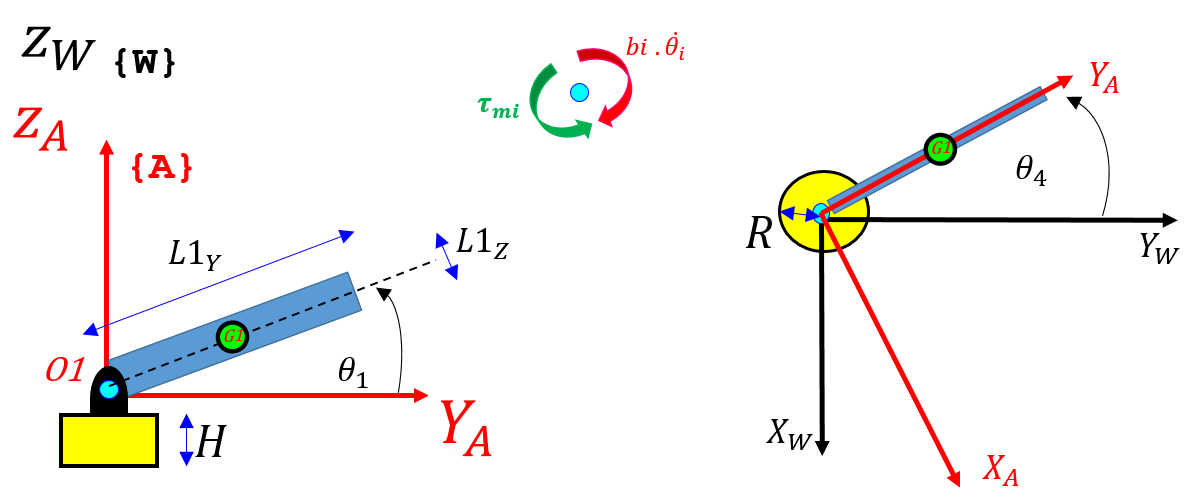       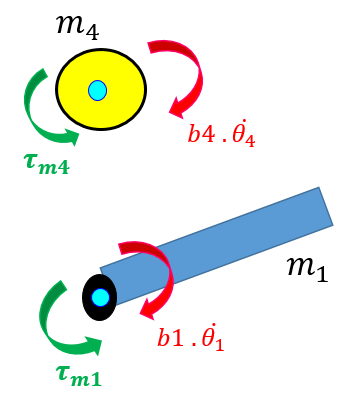

`Bradley Horton : 09-Mar-2017, bradley.horton@mathworks.com.au`

## Define some model parameters for our manipulator:

density = 1000; % kg/m3

## Define some geometry parameters for our Turntable:

Hz     = 0.20;  % m
Rturn  = 0.05;  % m  
mass4  = density * Hz*pi*(Rturn^2); % kg

## Define some geometry parameters for our LINKS:

L1y     = 0.75; % m
L1z     = 0.050; % m
L1x     = 0.005; % m
mass1   = density * L1x*L1y*L1z; % kg

## Define some damping at each joint:

We will assume that each pivot point experiences viscous damping, ie: $\tau_{damping} = b \thinspace \dot{\theta}$.   Note that the damping torque is a function of the relative joint velocity, eg: $\tau_2 = b_2 \thinspace . \thinspace \dot{\theta}_2$.

b1_damp = 0.005; %0.1 (N.m/(rad/sec));
b4_damp = 0.005; %0.1 (N.m/(rad/sec));

## Define gravity:

We'll assume that gravity acts in the negative Z-direction.

g = 9.80665;  % m/sec^2

## The System pose and INITIAL Conditions:

Here is how we'll describe the angular displacement of the 2 links.

    

Here are the system INITIAL conditions - note all units are either (rad) or (rad/sec)

- 
$$\theta_1(0) \qquad (rad)$$
             

- 
$$\dot{\theta}_1(0) \qquad (rad/sec)$$
                 

- 
$$\theta_4(0) \qquad (rad)$$
            

- 
$$\dot{\theta}_4(0) \qquad (rad/sec)$$
                 

theta1_0     =  45*pi/180;    % rad
theta1_dot_0 =  0;            % rad/sec 
theta4_0     =  30*pi/180;    % rad
theta4_dot_0 =  0;            % rad/sec 